# Robotics 2 - Midterm - April 13, 2016

## Exercise 1

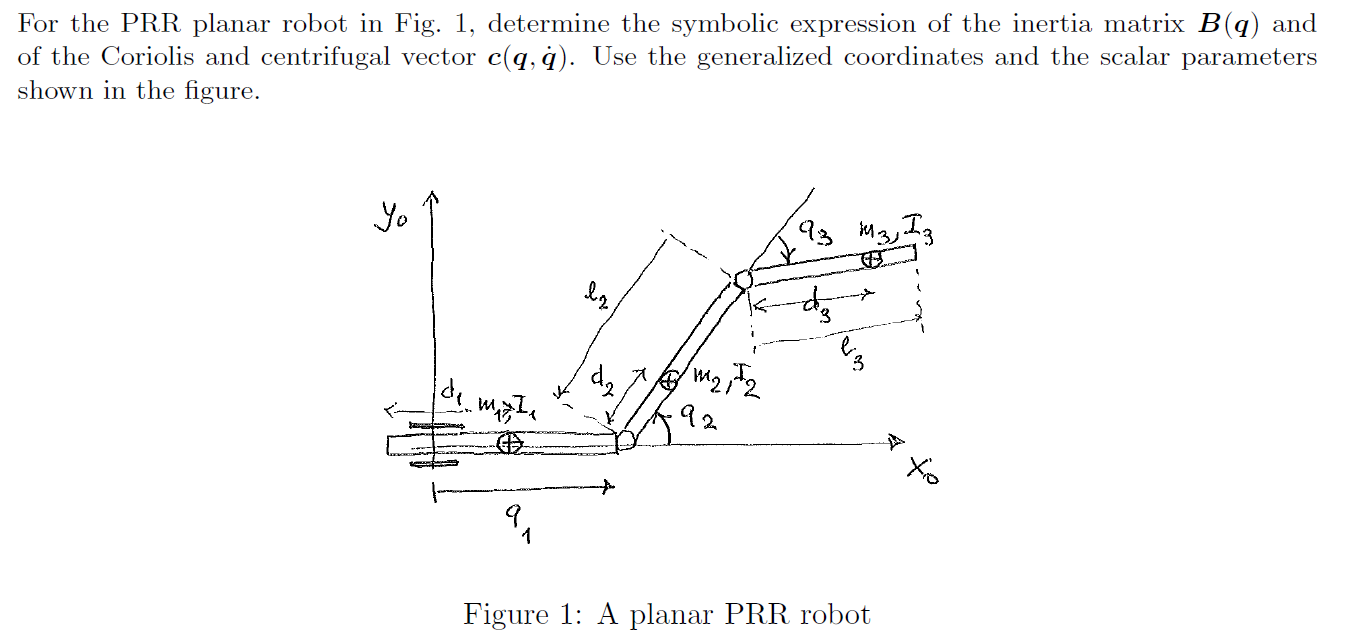

% clear;clc
% sigma = [1,0,0];
% n = length(sigma);
% q = sym('q', [1 n]);
% qd = sym('qd', [1 n]);
% qdd = sym('qdd', [1 n]); 
% d = sym('d', [1 n]);
% a = sym('a', [1 n]);
% l = sym('l', [1 n]);
% m = sym('m', [1 n]);
% I = sym('I', [1 n]);
% 
% %       alpha   a   d   theta
% dhTable = [pi/2     0       q(1)    0   ;
%            0        l(2)    0       q(2);
%            0        l(3)    0       q(3)]
% 
% 
% % % L(n)=LINK([theta D A alpha Sigma(optional) Offset(optional)])
% % % % % Must only specify either THETA or D
% % % % 
% % L(1) = Link('a', 0, 'alpha', pi/2,  'theta', pi/2,'qlim',[0,10]); % Prismatic
% % L(2) = Link('a', 10, 'alpha', 0, 'd', 0); % Revolute
% % L(3) = Link('a', 10, 'alpha', 0, 'd', 0); % Prismatic
% % prrRobot = SerialLink(L, 'name', 'PRR_Robot ')
% % prrRobot.teach
% 

### Manual Attempt

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,0,0];
% n = length(sigma);
% t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% qd = sym('qd', [n 1],'real');
% qdd = sym('qdd', [n 1],'real'); 
% 
% dc = sym('dc', [n 1],'real');
% k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% I = sym('I', [n 1],'real');
% 

% %Insert manually the global positions of the centers of mass
% pc(:,1) = [q(1) 0];
% pc(:,2) = [q(1)+k(1)+dc(2)*cos(q(2)), dc(2)*sin(q(2))];
% pc(:,3) = [q(1)+k(1)+l(2)*cos(q(2))+dc(3)*cos(q(2)+q(3)), l(2)*sin(q(2))+dc(3)*sin(q(2)+q(3))]
% [pct,qt]=ToTimedep(pc,n,'t','q')
% vct = diff(pct,t)
% [vc,q_d1,vc_short]=shortdiff(vct,sym2cell(qt),t,true,1,qd)%,[qd,qdd])
% w =[0, qd(2), qd(2)].';
% % for i=1:n
% %  T(i) = (1/2)*m(i)*(vc(:,i).'*vc(:,i)) + (1/2)*w(i)*I(i)*w(i);
% % end
% % KE = sum(T.')
% % 
% 

% 
% % R2Robot = [0 l(1) 0 q(1);
% %            0 l(2) 0 q(2)]
% 
% DHtable = [ 0    0       q(1)    0;
%             0    l(2)    0       q(2);
%             0    l(3)    0       q(3)
%             ]
% % [Jp, Jo,Jps, Jos] = getJacobian(DHtable,[1,0,0],'alpha')
% R2Robot=['prr';'xxx';[1,1,1]]       
% % R2Robot=['rr';'x~']       

% [Pc,vc,w,T,Ti,M] = getGenericPC(R2Robot,l,q,qd,dc,m,I)

%  [C,cac,Csubs,S] = getCs(M,q,qd)
%  [Msubs, dynamicParameters, a] = getDynamicParameters(M,q,[])%l')
% [Csubs,cacsubs,Csubssubs,Ssubs] = getCs(Msubs,q,qd)

## Torque full expression

%  
%  
% u =simplify( Msubs*qdd + cacsubs)

### Linear parametrization

% uY = collect(u,a);
% Y = [];
% for i = 1:length(a)
%     Y = [Y, diff(uY,a(i))];
% end
% Y


## exercise 2

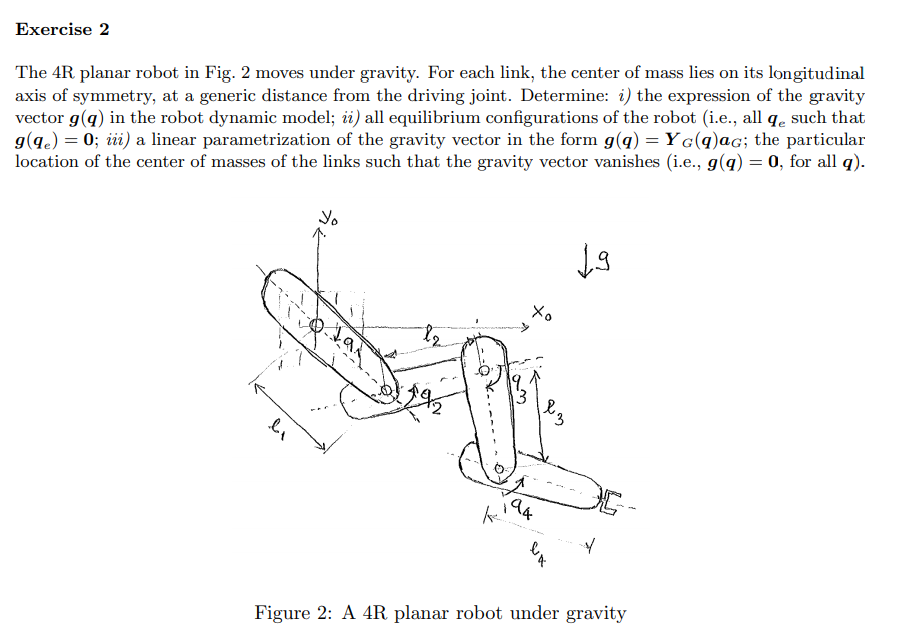

% This part is isolated from previous section
clear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [0,0,0,0];
n = length(sigma);
t = sym('t', 'real');
q = sym('q', [n 1],'real');
qd = sym('qd', [n 1],'real');
qdd = sym('qdd', [n 1],'real'); 

dc = sym('dc', [n 1],'real');
k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
I = sym('I', [n 1],'real');
g0 = sym('g0','real');
g=[0,-g0,0]';
isMotor=0;


% 
% % R2Robot = [0 l(1) 0 q(1);
% %            0 l(2) 0 q(2)]
% 
% DHtable = [ 0    0       q(1)    0;
%             0    l(2)    0       q(2);
%             0    l(3)    0       q(3)
%             ]
% % [Jp, Jo,Jps, Jos] = getJacobian(DHtable,[1,0,0],'alpha')
% R2Robot=['prr';'x~~']       
 R4Robot=['rrrr';'XXXX';[1,1,1,1]] 

R4Robot = 3×4 char array
    'rrrr'
    'XXXX'
    ''


[Pc,vc,w,T,Ti,M,VarShortRobot] = getGenericPC(R4Robot,l,q,qd,dc,m,I)

si falla aquí está el error


$$Pc = \begin{array}{l} \left(\begin{array}{cccc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & \sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sigma_{4} & {\mathrm{dc}}_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+\sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\sigma_{4}\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) & \sigma_{1}+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sigma_{3} & {\mathrm{dc}}_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+\sigma_{1}+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sigma_{3}\\ 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{3}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$w = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ {\mathrm{qd}}_{1} & {\mathrm{qd}}_{1}+{\mathrm{qd}}_{2} & {\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}+{\mathrm{qd}}_{3} & {\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}+{\mathrm{qd}}_{4} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×4 sym]
    vc: [3×4 sym]
     w: [3×4 sym]
     T: [1×1 sym]
    Ti: [1×4 sym]
     M: [4×4 sym]



 [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccccccccccccccccccccccccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{3}\right) & \sin\left(q_{4}\right) & \sin\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{3}\right) & \sin\left(q_{2}+q_{3}\right) & \sin\left(q_{1}+q_{4}\right) & \sin\left(q_{2}+q_{4}\right) & \sin\left(q_{3}+q_{4}\right) & \sin\left(q_{1}+q_{2}+q_{3}\right) & \sin\left(q_{1}+q_{2}+q_{4}\right) & \sin\left(q_{1}+q_{3}+q_{4}\right) & \sin\left(q_{2}+q_{3}+q_{4}\right) & \sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{3}\right) & \cos\left(q_{4}\right) & \cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{4}\right) & \cos\left(q_{2}+q_{4}\right) & \cos\left(q_{3}+q_{4}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{4}\right) & \cos\left(q_{1}+q_{3}+q_{4}\right) & \cos\left(q_{2}+q_{3}+q_{4}\right) & \cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right) \end{array}\right)$$

$$PE = g_{0}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)+g_{0}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\,\left({\mathrm{dc}}_{3}\,m_{3}+l_{3}\,m_{4}\right)+g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4}\right)+{\mathrm{dc}}_{4}\,g_{0}\,m_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)$$

$$PE\_short = g_{0}\,s_{1,2,3}\,\left({\mathrm{dc}}_{3}\,m_{3}+l_{3}\,m_{4}\right)+g_{0}\,s_{1,2}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)+g_{0}\,s_{1}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4}\right)+{\mathrm{dc}}_{4}\,g_{0}\,m_{4}\,s_{1,2,3,4}$$

$$g\_q\_short = \begin{array}{l} \left(\begin{array}{c} c_{1,2}\,g_{0}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)+c_{1}\,g_{0}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4}\right)+\sigma_{1}+c_{1,2,3,4}\,{\mathrm{dc}}_{4}\,g_{0}\,m_{4}\\ c_{1,2}\,g_{0}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)+\sigma_{1}+c_{1,2,3,4}\,{\mathrm{dc}}_{4}\,g_{0}\,m_{4}\\ \sigma_{1}+c_{1,2,3,4}\,{\mathrm{dc}}_{4}\,g_{0}\,m_{4}\\ c_{1,2,3,4}\,{\mathrm{dc}}_{4}\,g_{0}\,m_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=c_{1,2,3}\,g_{0}\,\left({\mathrm{dc}}_{3}\,m_{3}+l_{3}\,m_{4}\right) \end{array}$$

$$g\_q = \begin{array}{l} \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)+\sigma_{1}+g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4}\right)+\sigma_{2}\\ g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)+\sigma_{1}+\sigma_{2}\\ \sigma_{1}+\sigma_{2}\\ \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=g_{0}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\,\left({\mathrm{dc}}_{3}\,m_{3}+l_{3}\,m_{4}\right)\\ \sigma_{2}={\mathrm{dc}}_{4}\,g_{0}\,m_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right) \end{array}$$

$$PE = g_{0}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)+g_{0}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\,\left({\mathrm{dc}}_{3}\,m_{3}+l_{3}\,m_{4}\right)+g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4}\right)+{\mathrm{dc}}_{4}\,g_{0}\,m_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)$$

U = 1×4 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}    {1×1 sym}


$$g\_q\_short = \begin{array}{l} \left(\begin{array}{c} c_{1,2}\,g_{0}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)+c_{1}\,g_{0}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4}\right)+\sigma_{1}+c_{1,2,3,4}\,{\mathrm{dc}}_{4}\,g_{0}\,m_{4}\\ c_{1,2}\,g_{0}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)+\sigma_{1}+c_{1,2,3,4}\,{\mathrm{dc}}_{4}\,g_{0}\,m_{4}\\ \sigma_{1}+c_{1,2,3,4}\,{\mathrm{dc}}_{4}\,g_{0}\,m_{4}\\ c_{1,2,3,4}\,{\mathrm{dc}}_{4}\,g_{0}\,m_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=c_{1,2,3}\,g_{0}\,\left({\mathrm{dc}}_{3}\,m_{3}+l_{3}\,m_{4}\right) \end{array}$$

$$PE\_short = g_{0}\,s_{1,2,3}\,\left({\mathrm{dc}}_{3}\,m_{3}+l_{3}\,m_{4}\right)+g_{0}\,s_{1,2}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)+g_{0}\,s_{1}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4}\right)+{\mathrm{dc}}_{4}\,g_{0}\,m_{4}\,s_{1,2,3,4}$$

## linear parameterization part 1

 [g_subs, dynamicParametersG, aG] = getDynamicParameters(g_q,q,[])%l')

>> Getting dynamic coefficients. Might take a while...


params1term = 1×10 logical array
   1   1   1   1   1   1   1   1   1   1


MSubs First iteration


MSubs second iteration (before re-replacement)


$$g\_subs = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}+a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{3}\,\cos\left(q_{1}\right)+a_{1}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{1}+a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{1}+a_{1}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right) \end{array}$$

$$dynamicParametersG = \left(\begin{array}{c} g_{0}\,\left({\mathrm{dc}}_{3}\,m_{3}+l_{3}\,m_{4}\right)\\ g_{0}\,\left({\mathrm{dc}}_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)\\ g_{0}\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4}\right)\\ {\mathrm{dc}}_{4}\,g_{0}\,m_{4} \end{array}\right)$$

$$aG = \left(\begin{array}{cccc} a_{1} & a_{2} & a_{3} & a_{4} \end{array}\right)$$

## part 2

% 
 [Yg, Ygshort] = getLinearParametrization(g_subs,aG)


## Exercise 3

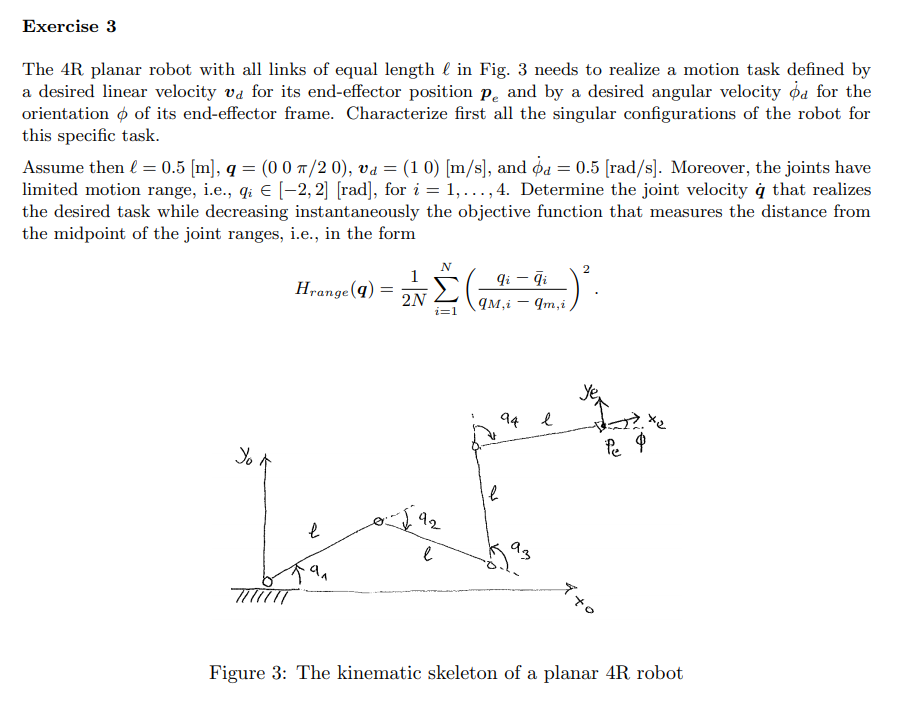

% This part is isolated from previous section
clear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [0,0,0,0];
n = length(sigma);
t = sym('t', 'real');
q = sym('q', [n 1],'real');
q0 = sym('q0', [n 1],'real');
qM = sym('qM', [n 1],'real');
qm = sym('qm', [n 1],'real');


qd = sym('qd', [n 1],'real');
qdd = sym('qdd', [n 1],'real'); 

dc = sym('dc', [n 1],'real');
k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');

l0=[l(1),l(1),l(1),l(1)]'
m = sym('m', [n 1],'real');
I = sym('I', [n 1],'real');
g0 = sym('g0','real');
pd = sym('pd0', [3 1],'real');
g=[0,-g0,0]';
isMotor=0;

l0_=[0.5,0.5,0.5,0.5]'
q0_=[0,0,0,0]'
q_=[0,0,pi/2,0]'
qm_=[-2,-2,-2,-2]'%qmin
qM_=[2,2,2,2]'%qmax
vd=[1,0]';
thetad=[0.5];
rd_=[vd;thetad];
VArsToRe=[l0;q]
VArsToRe_=[l0_;q_]
VArsToRe2=[q;q0;qm;qM]
VArsToRe2_=[q_;q0_;qm_;qM_]
VArsToRe_=[l0_;q_]
[H, grad_H_range] = HrangeFun(q, qm_,qM_)

% R2Robot=['prr';'x~~']       
 R4Robot=['rrrr';'XXXX'] ;
[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R4Robot,l0,q,qd,dc,m,I)

J_=subs(J,VArsToRe,VArsToRe_)
J_ps_=pinv(J_)
grad_H_range_=(subs(grad_H_range,VArsToRe2,VArsToRe2_))
[qd,qd_] = ProjectedGradient(q,0,J_,rd_,H,grad_H_range_,q_)
digits(5)
vpa(qd_)